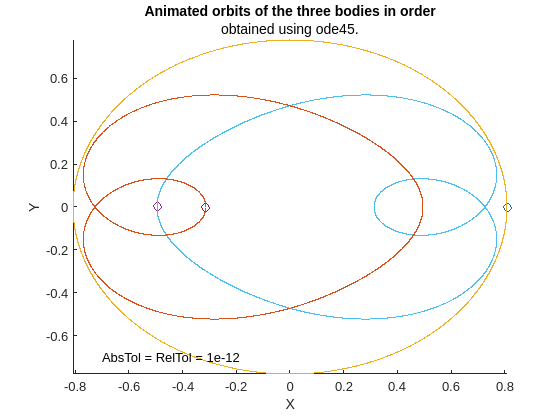

% Beggining of script, clearing all variables from previous script runs.
clearvars

% Task 1 ****************************************

% Defining the vector describing the position, as well as the velocities for each
% body. it is initialized with the initial conditions. The vector is of the
% following form: z = [x1, y1, vx1, vy1, x2, y2, vx2, vy2, x3, y3, vx3, vy3]
%                      1   2   3    4    5   6   7    8    9   10  11   12
z = [ 0.8083106230 ; 0 ; 0 ; 0.9901979166 ; -0.4954148566 ; 0 ; 0 ; -2.7171431768 ; -0.3128957664 ; 0 ; 0 ; 1.7269452602 ];

% Defining the time span and time step. The time span is chosen according to
% the assignment description.
T = 5.226525;
p = -5;
dt = 10^p;

% Defining known constants used in the set of equations.
G = 1;
m1 = 1;
m2 = 1;
m3 = 1;

% Defining the function describing the distances between the bodies.
r12 = @(Z) sqrt((Z(1) - Z(5))^2 + (Z(2) - Z(6))^2);
r23 = @(Z) sqrt((Z(5) - Z(9))^2 + (Z(6) - Z(10))^2);
r13 = @(Z) sqrt((Z(1) - Z(9))^2 + (Z(2) - Z(10))^2);

% Defining the set of ODEs to be solved 
f = @(t,Z) [
 Z(3);
 Z(4);
 -G*m2*(Z(1) - Z(5))/r12(Z)^3 - G*m3*(Z(1) - Z(9))/r13(Z)^3;
 -G*m2*(Z(2) - Z(6))/r12(Z)^3 - G*m3*(Z(2) - Z(10))/r13(Z)^3;
 Z(7);
 Z(8);
 -G*m3*(Z(5) - Z(9))/r23(Z)^3 - G*m1*(Z(5) - Z(1))/r12(Z)^3;
 -G*m3*(Z(6) - Z(10))/r23(Z)^3 - G*m1*(Z(6) - Z(2))/r12(Z)^3;
 Z(11);
 Z(12);
 -G*m1*(Z(9) - Z(1))/r13(Z)^3 - G*m2*(Z(9) - Z(5))/r23(Z)^3;
 -G*m1*(Z(10) - Z(2))/r13(Z)^3 - G*m2*(Z(10) - Z(6))/r23(Z)^3;
];

% Obtaining the matrix of numerical values representing the solution of the
% set of ODEs in the time interval [0,T]. It is obtained using ode45. The absolute and relative tolerance is
% set to 10^-12 using odeset.
options = odeset('RelTol',1e-12,'AbsTol',1e-12);
[ts,R0] = ode45(f,[0 T],z,options);

% Obtaining the matrix of numerical values representing the solution of the
% set of ODEs in the time interval [0,T]. It is obtained using the second
% order Adam-Bashford method.
z_AB = AB2(f,dt,T,z);

% Obtaining the matrix of numerical values representing the solution of the
% set of ODEs in the time interval [0,T]. It is obtained using the Kutta method.
z_K = Kut(f,dt,T,z);

% Obtaining the matrix of numerical values representing the solution of the set of 
% ODEs in the time interval [0,T]. It is obtained using the classical Runge-Kutta method.
z_RK = RK4(f,dt,T,z);

% Code for generation of figure 1,2,3,4,5,6,7.
txt = "h = "+dt;

comet(R0(:,1),R0(:,2))
hold on;
comet(R0(:,5),R0(:,6))
comet(R0(:,9),R0(:,10))
title("Animated orbits of the three bodies in order", "obtained using ode45.")
xlabel("X")
ylabel("Y")
text(-0.7,-0.7,"AbsTol = RelTol = 1e-12");
hold off;

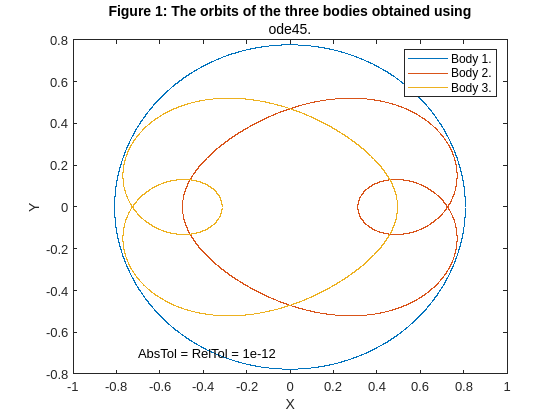


figure(1)
clf
plot(R0(:,1),R0(:,2))
hold on;
plot(R0(:,5),R0(:,6))
plot(R0(:,9),R0(:,10))
legend("Body 1.","Body 2.","Body 3.");
title("Figure 1: The orbits of the three bodies obtained using", "ode45.")
xlabel("X")
ylabel("Y")
text(-0.7,-0.7,"AbsTol = RelTol = 1e-12");
hold off;

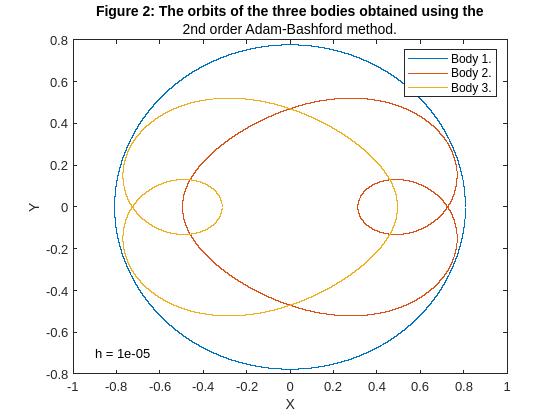


figure(2)
clf
plot(z_AB(1,:),z_AB(2,:))
hold on;
plot(z_AB(5,:),z_AB(6,:))
plot(z_AB(9,:),z_AB(10,:))
legend("Body 1.","Body 2.","Body 3.");
title("Figure 2: The orbits of the three bodies obtained using the", "2nd order Adam-Bashford method.")
xlabel("X")
ylabel("Y")
text(-0.9,-0.7,txt);
hold off;

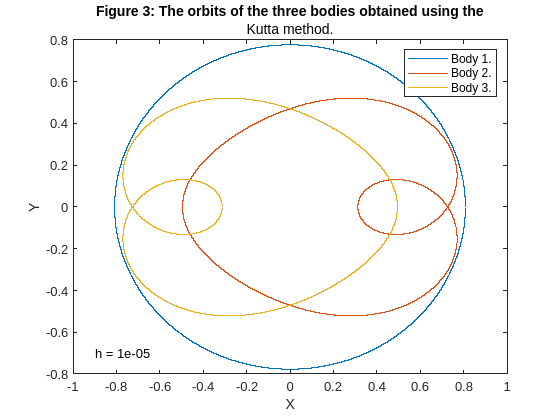


figure(3)
clf
plot(z_K(1,:),z_K(2,:))
hold on;
plot(z_K(5,:),z_K(6,:))
plot(z_K(9,:),z_K(10,:))
legend("Body 1.","Body 2.","Body 3.");
title("Figure 3: The orbits of the three bodies obtained using the", "Kutta method.")
xlabel("X")
ylabel("Y")
text(-0.9,-0.7,txt);
hold off;

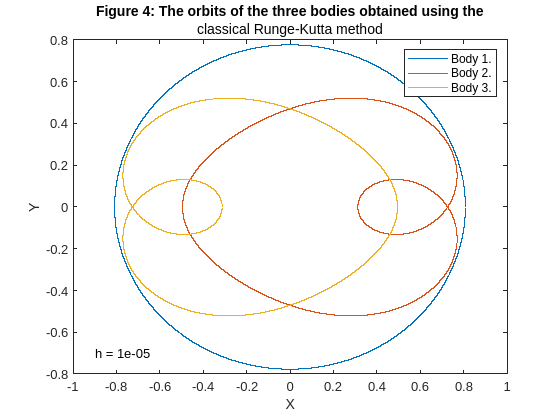


figure(4)
clf
plot(z_RK(1,:),z_RK(2,:))
hold on;
plot(z_RK(5,:),z_RK(6,:))
plot(z_RK(9,:),z_RK(10,:))
legend("Body 1.","Body 2.","Body 3.");
title("Figure 4: The orbits of the three bodies obtained using the", "classical Runge-Kutta method")
xlabel("X")
ylabel("Y")
text(-0.9,-0.7,txt);
hold off;

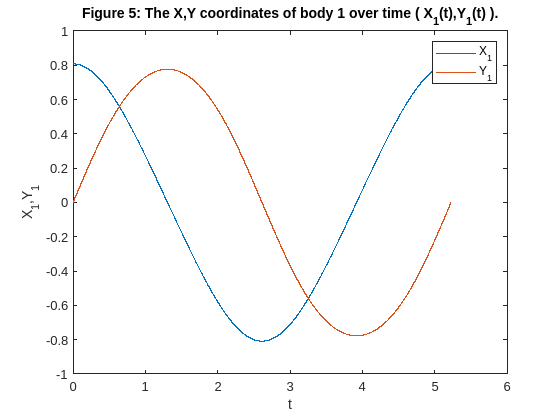


figure(5)
clf
plot(ts,R0(:,1));
hold on;
plot(ts,R0(:,2));
title("Figure 5: The X,Y coordinates of body 1 over time ( X_{1}(t),Y_{1}(t) ).");
legend("X_{1}","Y_{1}")
xlabel("t")
ylabel("X_{1},Y_{1}")
hold off;

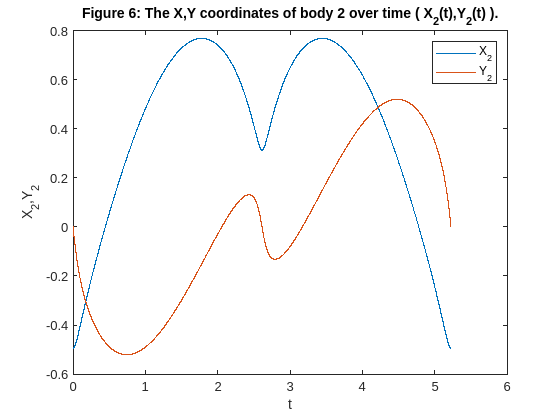


figure(6)
clf
plot(ts,R0(:,5));
hold on;
plot(ts,R0(:,6));
legend("X_{2}","Y_{2}")
title("Figure 6: The X,Y coordinates of body 2 over time ( X_{2}(t),Y_{2}(t) ).");
xlabel("t")
ylabel("X_{2},Y_{2}")
hold off;

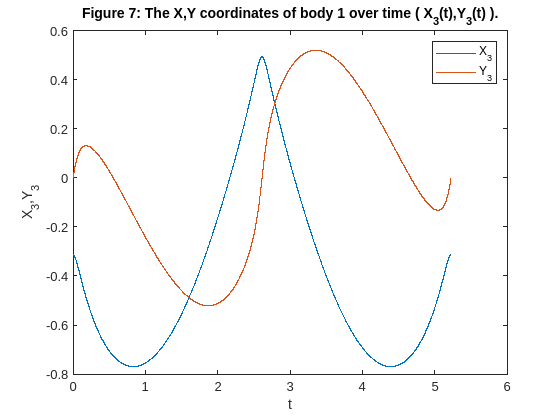


figure(7)
clf
plot(ts,R0(:,9));
hold on;
plot(ts,R0(:,10));
legend("X_{3}","Y_{3}")
title("Figure 7: The X,Y coordinates of body 1 over time ( X_{3}(t),Y_{3}(t) ).");
xlabel("t")
ylabel("X_{3},Y_{3}")
hold off;

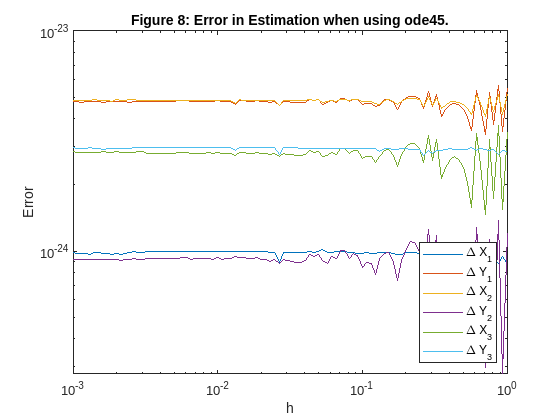


% Task 3 ****************************************
% Setting value of constant r0. It is set to the value obtained
% analytically in task 2 using the particular analytical solution.
r0 = -1;

% Defining the time span and time step. The time span is chosen according to
% the assignment description.
T = 2*pi;
N = 100;
dt_values = logspace(-3,0,N);

% Setting the values of the constant G and the masses.
G = 1;
m1 = sqrt(3);
m2 = sqrt(3);
m3 = sqrt(3);

% Refefining f to update the values of the constant G and the masses.
f = @(t,Z) [
 Z(3);
 Z(4);
 -G*m2*(Z(1) - Z(5))/r12(Z)^3 - G*m3*(Z(1) - Z(9))/r13(Z)^3;
 -G*m2*(Z(2) - Z(6))/r12(Z)^3 - G*m3*(Z(2) - Z(10))/r13(Z)^3;
 Z(7);
 Z(8);
 -G*m3*(Z(5) - Z(9))/r23(Z)^3 - G*m1*(Z(5) - Z(1))/r12(Z)^3;
 -G*m3*(Z(6) - Z(10))/r23(Z)^3 - G*m1*(Z(6) - Z(2))/r12(Z)^3;
 Z(11);
 Z(12);
 -G*m1*(Z(9) - Z(1))/r13(Z)^3 - G*m2*(Z(9) - Z(5))/r23(Z)^3;
 -G*m1*(Z(10) - Z(2))/r13(Z)^3 - G*m2*(Z(10) - Z(6))/r23(Z)^3;
];

% Defining the new initial conditions.
z = [
r0*sin(-pi/2) ;
r0*cos(-pi/2) ;
r0*cos(-pi/2) ;
-r0*sin(-pi/2) ;
r0*sin(pi/6) ;
r0*cos(pi/6) ;
r0*cos(pi/6) ;
-r0*sin(pi/6) ;
r0*sin(pi*5/6) ;
r0*cos(pi*5/6) ;
r0*cos(pi*5/6) ;
-r0*sin(pi*5/6) ;
];

% Defining the function represeting the particular solution to the set of
% ODEs.
PS = @(t) [
   r0*sin(t-pi/2) ;
   r0*cos(t-pi/2) ;
   r0*sin(t+pi/6) ;
   r0*cos(t+pi/6) ;
   r0*sin(t+(5*pi)/6) ;
   r0*cos(t+(5*pi)/6) ;
];

%initializing variables used for the storing of error
timespan = 0:dt_values(1):T;
M = size(timespan,2);

ms_OD = zeros(6,N);
ms_AB = zeros(6,N);
ms_K = zeros(6,N);
ms_RK = zeros(6,N);

% Error when using ode45 to obtain a numerical estimate of the trajectories.
for i1 = 1:N
    timespan = 0:dt_values(i1):T;
    M = size(timespan,2);

    r = PS(timespan);   
    ErrOD = zeros(6,M);

    [ts,R] = ode45(f,timespan,z,options);
    EstOD = R';
    ErrOD(1,:) = EstOD(1,:) - r(1,:);
    ErrOD(2,:) = EstOD(2,:) - r(2,:);
    ErrOD(3,:) = EstOD(5,:) - r(3,:);
    ErrOD(4,:) = EstOD(6,:) - r(4,:);
    ErrOD(5,:) = EstOD(9,:) - r(5,:);
    ErrOD(6,:) = EstOD(10,:) - r(6,:);

    ErrOD = ErrOD.^2;
    for i2 = 1:6
        ms_OD(i2,i1) = (1/M)*sum(ErrOD(i2,:));
    end
end

% Error when using the 2nd order Adam-Bashford to obtain a numerical estimate of the trajectories.
for j1 = 1:N
    timespan = 0:dt_values(j1):T;
    M = size(timespan,2);

    r = PS(timespan);  
    ErrAB = zeros(6,M);

    EstAB = AB2(f,dt_values(j1),T,z);
    ErrAB(1,:) = EstAB(1,:) - r(1,:);
    ErrAB(2,:) = EstAB(2,:) - r(2,:);
    ErrAB(3,:) = EstAB(5,:) - r(3,:);
    ErrAB(4,:) = EstAB(6,:) - r(4,:);
    ErrAB(5,:) = EstAB(9,:) - r(5,:);
    ErrAB(6,:) = EstAB(10,:) - r(6,:);

    ErrAB = ErrAB.^2;
    for j2 = 1:6
        ms_AB(j2,j1) = (1/M)*sum(ErrAB(j2,:));
    end
end

% Error when using the kutta method to obtain a numerical estimate of the trajectories.
for l1 = 1:N
    timespan = 0:dt_values(l1):T;
    M = size(timespan,2);

    r = PS(timespan);    
    ErrK = zeros(6,M);

    EstK = Kut(f,dt_values(l1),T,z);
    ErrK(1,:) = EstK(1,:) - r(1,:);
    ErrK(2,:) = EstK(2,:) - r(2,:);
    ErrK(3,:) = EstK(5,:) - r(3,:);
    ErrK(4,:) = EstK(6,:) - r(4,:);
    ErrK(5,:) = EstK(9,:) - r(5,:);
    ErrK(6,:) = EstK(10,:) - r(6,:);

    ErrK = ErrK.^2;
    for l2 = 1:6
        ms_K(l2,l1) = (1/M)*sum(ErrK(l2,:));
    end
end

% Error when using the Runge-Kutta method to obtain a numerical estimate of the trajectories.
for k1 = 1:N
    timespan = 0:dt_values(k1):T;
    M = size(timespan,2);

    r = PS(timespan);    
    ErrRK = zeros(6,M);

    EstRK = RK4(f,dt_values(k1),T,z);
    ErrRK(1,:) = EstRK(1,:) - r(1,:);
    ErrRK(2,:) = EstRK(2,:) - r(2,:);
    ErrRK(3,:) = EstRK(5,:) - r(3,:);
    ErrRK(4,:) = EstRK(6,:) - r(4,:);
    ErrRK(5,:) = EstRK(9,:) - r(5,:);
    ErrRK(6,:) = EstRK(10,:) - r(6,:);

    ErrRK = ErrRK.^2;
    for k2 = 1:6
        ms_RK(k2,k1) = (1/M)*sum(ErrRK(k2,:));
    end
end

% Code for generation of figure 8,9,10,11.
figure(8)
clf
loglog(dt_values,ms_OD(1,:));
hold on
for i = 2:6
    loglog(dt_values,ms_OD(i,:));
end
title("Figure 8: Error in Estimation when using ode45.");
legend("\Delta X_{1}","\Delta Y_{1}","\Delta X_{2}","\Delta Y_{2}","\Delta X_{3}","\Delta Y_{3}",'Location','southeast');
xlabel("h")
ylabel("Error")
hold off;

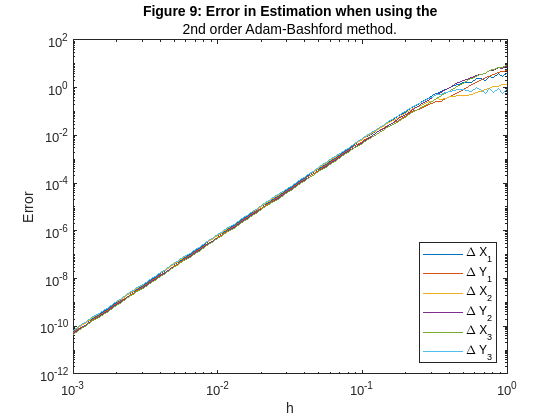


figure(9)
clf
loglog(dt_values,ms_AB(1,:));
hold on
for i = 2:6
    loglog(dt_values,ms_AB(i,:));
end
title("Figure 9: Error in Estimation when using the", "2nd order Adam-Bashford method.");
legend("\Delta X_{1}","\Delta Y_{1}","\Delta X_{2}","\Delta Y_{2}","\Delta X_{3}","\Delta Y_{3}",'Location','southeast');
xlabel("h")
ylabel("Error")
hold off;

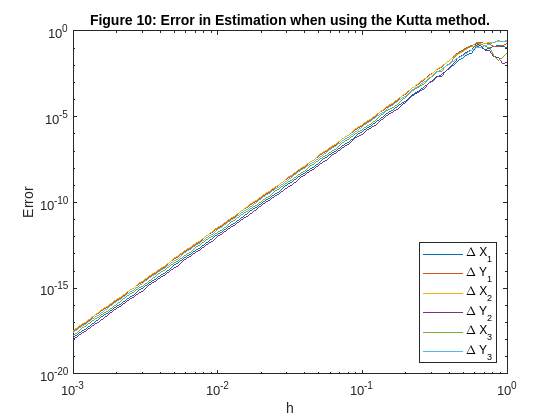


figure(10)
clf
loglog(dt_values,ms_K(1,:));
hold on
for i = 2:6
    loglog(dt_values,ms_K(i,:));
end
title("Figure 10: Error in Estimation when using the Kutta method.");
legend("\Delta X_{1}","\Delta Y_{1}","\Delta X_{2}","\Delta Y_{2}","\Delta X_{3}","\Delta Y_{3}",'Location','southeast');
xlabel("h")
ylabel("Error")
hold off;

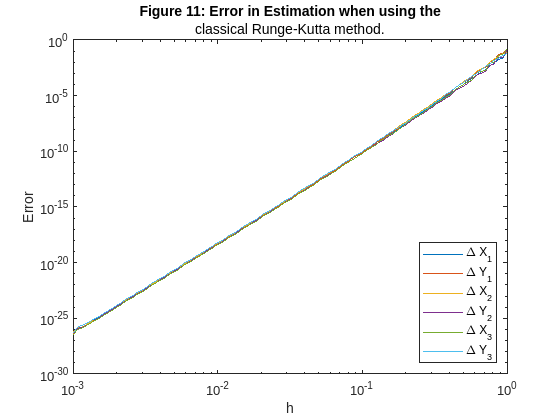


figure(11)
clf
loglog(dt_values,ms_RK(1,:));
hold on
for i = 2:6
    loglog(dt_values,ms_RK(i,:));
end
title("Figure 11: Error in Estimation when using the", "classical Runge-Kutta method.");
legend("\Delta X_{1}","\Delta Y_{1}","\Delta X_{2}","\Delta Y_{2}","\Delta X_{3}","\Delta Y_{3}",'Location','southeast');
xlabel("h")
ylabel("Error")
hold off;


% Task 4 ****************************************
% Reading the table of data13, and from it the time span used in the measurements. 

j = @J;

p = fminsearch(j,[1,1,1]);

p =     1.1648    1.1409    1.0826


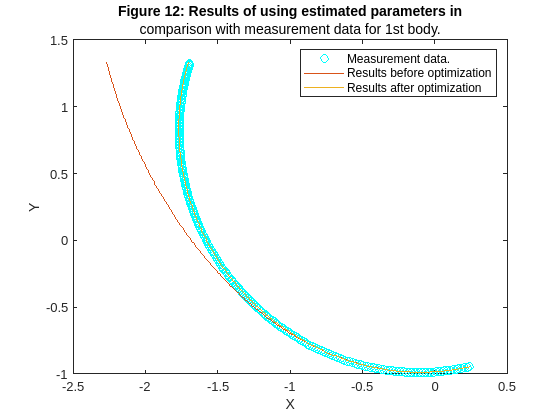


data13 = readtable("Documents/MATLAB/enume-2024-mahmoud-elshekh-ali-323930/Assignment C/data_13.csv");
data13 = data13{:,:};
timespan = 0:0.02:5;

G = 1;
m1 = p(1);
m2 = p(2);
m3 = p(3);

z = [
    data13(1,2);
    data13(1,3);
    (data13(2,2) - data13(1,2))/0.02;
    (data13(2,3) - data13(1,3))/0.02;
    data13(1,4);
    data13(1,5);
    (data13(2,4) - data13(1,4))/0.02;
    (data13(2,5) - data13(1,5))/0.02;
    data13(1,6);
    data13(1,7);
    (data13(2,6) - data13(1,6))/0.02;
    (data13(2,7) - data13(1,7))/0.02;
    ];

f = @(t,Z) [
 Z(3);
 Z(4);
 -G*m2*(Z(1) - Z(5))/r12(Z)^3 - G*m3*(Z(1) - Z(9))/r13(Z)^3;
 -G*m2*(Z(2) - Z(6))/r12(Z)^3 - G*m3*(Z(2) - Z(10))/r13(Z)^3;
 Z(7);
 Z(8);
 -G*m3*(Z(5) - Z(9))/r23(Z)^3 - G*m1*(Z(5) - Z(1))/r12(Z)^3;
 -G*m3*(Z(6) - Z(10))/r23(Z)^3 - G*m1*(Z(6) - Z(2))/r12(Z)^3;
 Z(11);
 Z(12);
 -G*m1*(Z(9) - Z(1))/r13(Z)^3 - G*m2*(Z(9) - Z(5))/r23(Z)^3;
 -G*m1*(Z(10) - Z(2))/r13(Z)^3 - G*m2*(Z(10) - Z(6))/r23(Z)^3;
];

[ts,R1] = ode45(f,timespan,z);

G = 1;
m1 = 1;
m2 = 1;
m3 = 1;

f = @(t,Z) [
 Z(3);
 Z(4);
 -G*m2*(Z(1) - Z(5))/r12(Z)^3 - G*m3*(Z(1) - Z(9))/r13(Z)^3;
 -G*m2*(Z(2) - Z(6))/r12(Z)^3 - G*m3*(Z(2) - Z(10))/r13(Z)^3;
 Z(7);
 Z(8);
 -G*m3*(Z(5) - Z(9))/r23(Z)^3 - G*m1*(Z(5) - Z(1))/r12(Z)^3;
 -G*m3*(Z(6) - Z(10))/r23(Z)^3 - G*m1*(Z(6) - Z(2))/r12(Z)^3;
 Z(11);
 Z(12);
 -G*m1*(Z(9) - Z(1))/r13(Z)^3 - G*m2*(Z(9) - Z(5))/r23(Z)^3;
 -G*m1*(Z(10) - Z(2))/r13(Z)^3 - G*m2*(Z(10) - Z(6))/r23(Z)^3;
];

[ts,R2] = ode45(f,timespan,z);

% Code for generation of figure 12,13,14.
figure(12)
clf
plot(data13(:,2),data13(:,3),'oc','LineWidth',0.1)
hold on;
plot(R2(:,1),R1(:,2));
plot(R1(:,1),R1(:,2));
xlabel("X")
ylabel("Y")
title("Figure 12: Results of using estimated parameters in", "comparison with measurement data for 1st body.");
legend("Measurement data.","Results before optimization","Results after optimization");

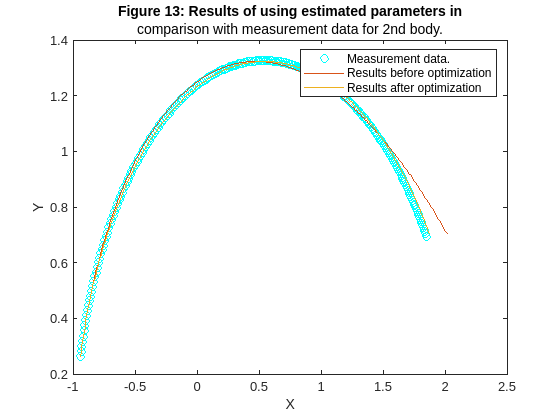


figure(13)
clf
plot(data13(:,4),data13(:,5),'oc','LineWidth',0.1)
hold on;
plot(R2(:,5),R1(:,6));
plot(R1(:,5),R1(:,6));
xlabel("X")
ylabel("Y")
title("Figure 13: Results of using estimated parameters in", "comparison with measurement data for 2nd body.");
legend("Measurement data.","Results before optimization","Results after optimization");

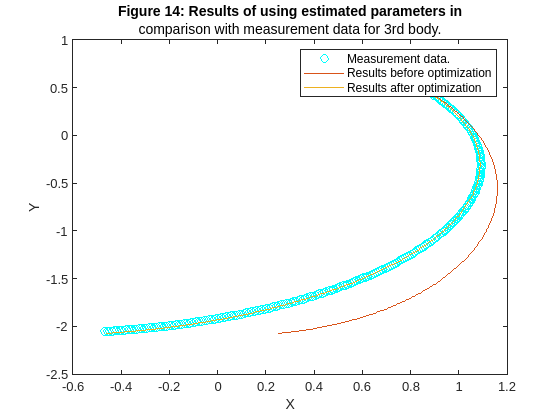


figure(14)
clf
plot(data13(:,6),data13(:,7),'oc','LineWidth',0.1)
hold on;
plot(R2(:,9),R1(:,10));
plot(R1(:,9),R1(:,10));
xlabel("X")
ylabel("Y")
title("Figure 14: Results of using estimated parameters in", "comparison with measurement data for 3rd body.");
legend("Measurement data.","Results before optimization","Results after optimization");